# Proof of Concept: 1-D Fully Input Convex Neural Networks

This script provides an illustration of constrained deep learning for 1-dimensional convex networks, along with the boundedness guarantees discussed for 1-dimensional convex functions. This example shows these steps:

- Generate a dataset with some sinusoidal additive noise contaminating a convex function signal.

- Prepare the dataset for custom training loop.

- Create a fully input convex neural network (FICNN) architecture.

- Train the FICNN using a custom training loop and apply projected gradient descent to guarantee convexity.

- Train a comparable MLP network without architectural or weight constraints.

- Compare the two networks and show convexity is violated in the unconstrained network.

- Compute guaranteed bounds of the FICNN over the interval and test the validity of these bounds with network inference on this domain.

- Show these bounds are violated for the unconstrained MLP.

## Generate Data

First, take the convex function `y=x^4` and uniformly randomly sample this over the interval `[-1,1]`. Add sinusoidal noise to create a dataset. You can change the number of random samples if you want to experiment.

numSamples = 512;
rng(0);
xTrain = -2*rand(numSamples,1)+1; % [-1 1]
xTrain = sort(xTrain);
tTrain = xTrain.^4 + 0.2*sin(20*xTrain);

Visualize the data.

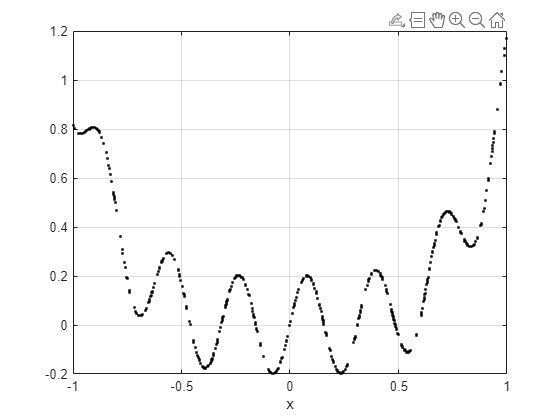

figure
plot(xTrain,tTrain,"k.")
grid on
xlabel("x")

## Prepare Data

To prepare the data for custom training loops, add the input and response to a `minibatchqueue`. You can do this by creating `arrayDatastore` objects and combining these into a single datastore using the `combine` function. Form the `minibatchqueue` with this combined datastore object.

xds = arrayDatastore(xTrain);
tds = arrayDatastore(tTrain);
cds = combine(xds,tds);

mbqTrain = minibatchqueue(cds,2, ...
    "MiniBatchSize",numSamples, ...
    "OutputAsDlarray",[1 1], ...
    "MiniBatchFormat",["BC","BC"]);

## Create FICNN

As discussed in [AI Verification: Convex](matlab:open('..\..\..\documentation\AI-Verification-Convexity.md')), fully input convex neural networks adhere to a specific class of neural network architectures with constraints applied to weights. In this proof of concept example, you build a simple FICNN using fully connected layers and ReLU activation functions. For more information on the architectural construction, see [AI Verification: Convex](matlab:open('..\..\..\documentation\AI-Verification-Convexity.md')).

inputSize = 1;
numHiddenUnits = [16 8 4 1];
ficnnet = buildConstrainedNetwork("fully-convex",inputSize,numHiddenUnits, ...
    ConvexNonDecreasingActivation="relu")

ficnnet =   dlnetwork with properties:

         Layers: [14×1 nnet.cnn.layer.Layer]
    Connections: [16×2 table]
     Learnables: [14×3 table]
          State: [0×3 table]
     InputNames: {'input'}
    OutputNames: {'add_4'}
    Initialized: 1

  View summary with summary.


You can view the network architecture in `deepNetworkDesigner` by setting the `viewNetworkDND` flag to `true`. Otherwise, plot the network graph.

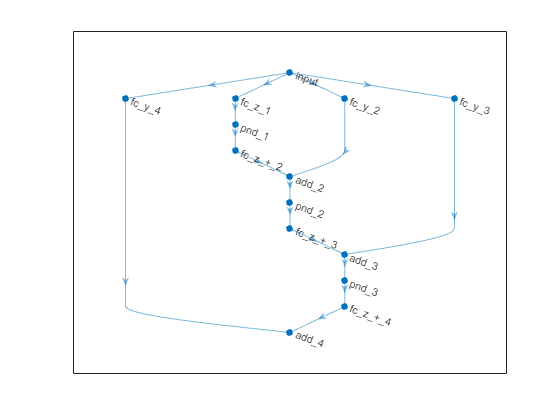

viewNetworkDND = false;
if viewNetworkDND
    deepNetworkDesigner(ficnnet) %#ok<UNRCH>
else
    figure;
    plot(ficnnet)
end

## Train FICNN

First, create a custom training options struct. For the `trainConvexNetwork` function, you can specify 4 hyperparameters: `maxEpochs`, `initialLearnRate`, `decay`, and `lossMetric`.

maxEpochs = 1200;
initialLearnRate = 0.05;
decay = 0.01;
lossMetric = "mae";

Train the network with these options.

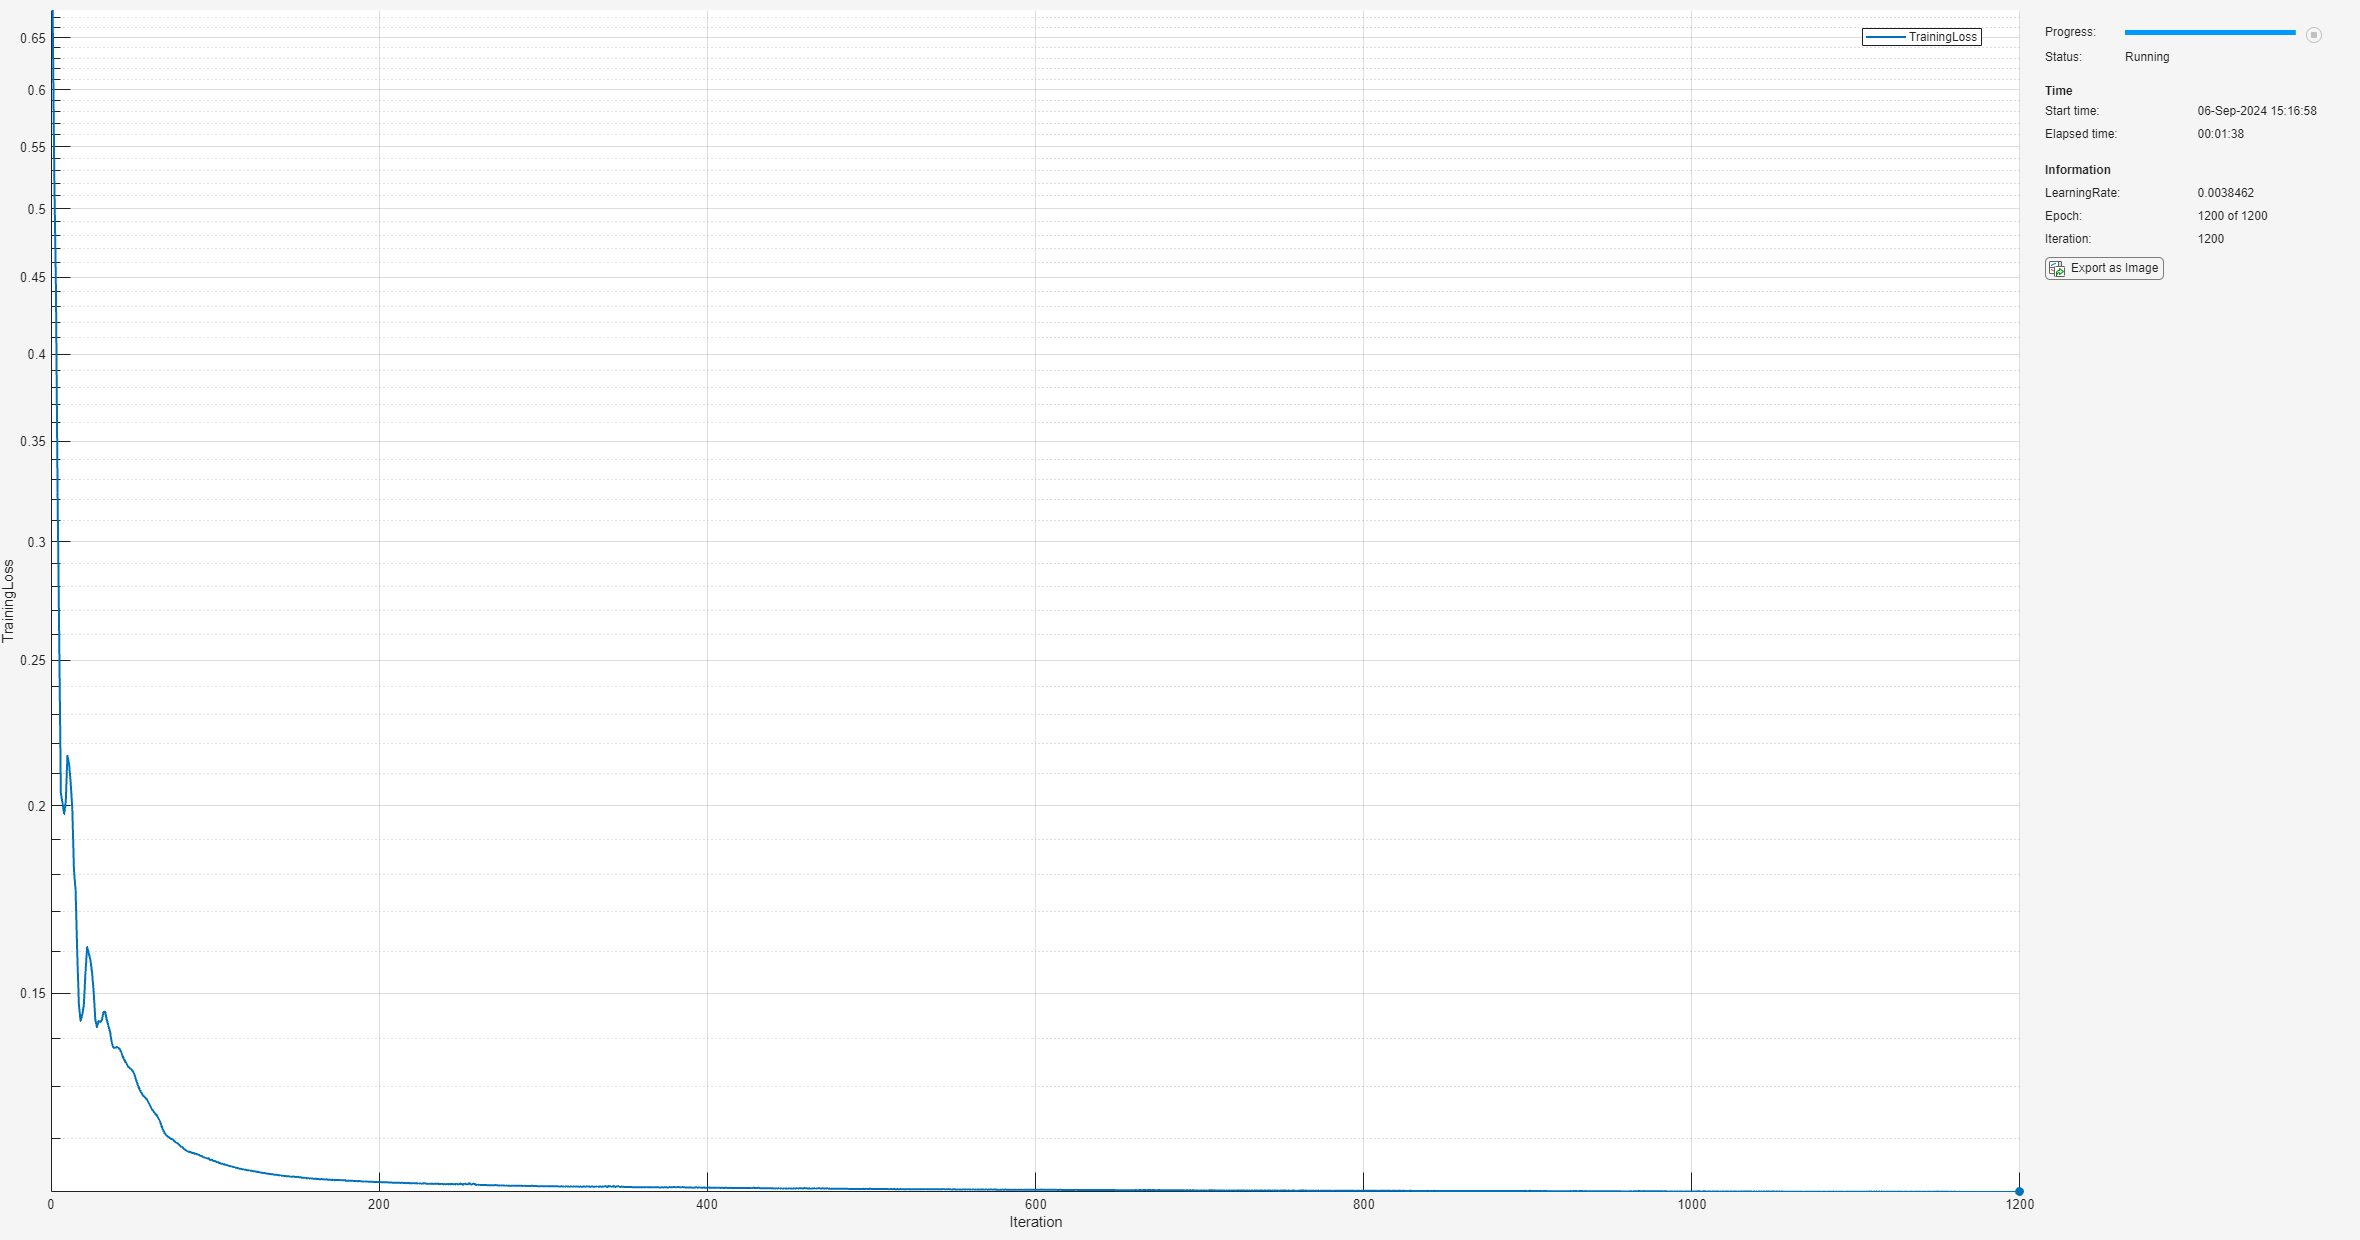

trained_ficnnet = trainConstrainedNetwork("fully-convex",ficnnet,mbqTrain, ...
   MaxEpochs=maxEpochs, ...
   InitialLearnRate=initialLearnRate, ...
   Decay=decay, ...
   LossMetric=lossMetric);

Evaluate the accuracy on the true underlying convex function from an independent random sampling from the interval `[-1,1]`.

rng(1);
xTest = -2*rand(numSamples,1)+1; % [-1 1]
tTest = xTest.^4;
lossAgainstUnderlyingSignal = computeLoss(trained_ficnnet,xTest,tTest,lossMetric)

lossAgainstUnderlyingSignal =

  gpuArray single

    0.0362



## Train Unconstrained MLP

Create a multi-layer perception as a comparison, with the same depth as the FICNN defined previously. Increase the number of activations to give the network capacity to fit and roughly compensate for the lack of skip connections in terms of learnable parameter count.

mlpHiddenUnits = numHiddenUnits;
layers = featureInputLayer(inputSize,Normalization="none");

for ii=1:numel(mlpHiddenUnits)-1
  
    layers = [layers ...
        fullyConnectedLayer(mlpHiddenUnits(ii)*2) ...
        tanhLayer];
end

% Add a final fully connected layer
layers = [layers ...
    fullyConnectedLayer(mlpHiddenUnits(end))];

Initialize the network.

rng(0);
mlpnet = dlnetwork(layers);

Again, you can view the network architecture in `deepNetworkDesigner` by setting the `viewNetworkDND` flag to `true`. Otherwise, plot the network graph.

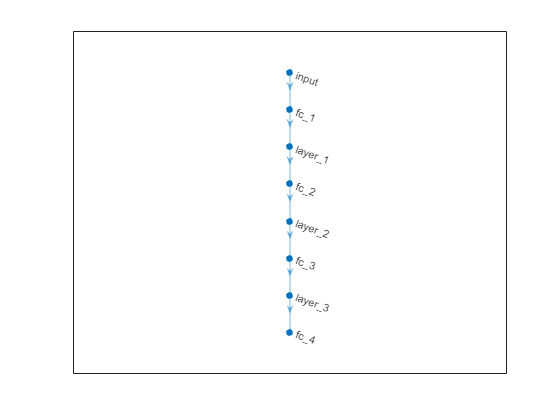

viewNetworkDND = false;
if viewNetworkDND
    deepNetworkDesigner(mlpnet) %#ok<UNRCH>
else
    figure;
    plot(mlpnet)
end

Specify the training options and then train the network using the `trainnet` function.

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss
    _________    _____    ___________    _________    ____________
            1        1       00:00:00         0.05         0.26302
           50       50       00:00:04        0.045         0.12781
          100      100       00:00:07      0.03645         0.12262
          150      150       00:00:09     0.032805         0.10938
          200      200       00:00:12     0.026572         0.10655
          250      250       00:00:15     0.021523         0.11237
          300      300       00:00:17     0.019371           0.104
          350      350       00:00:20     0.015691         0.10177
          400      400       00:00:23     0.012709        0.097083
          450      450       00:00:26     0.011438        0.094851
          500      500       00:00:28    0.0092651        0.092311
          550      550       00:00:31    0.0075047        0.093058
          600      600       00:00:34    0.0067543        0.08

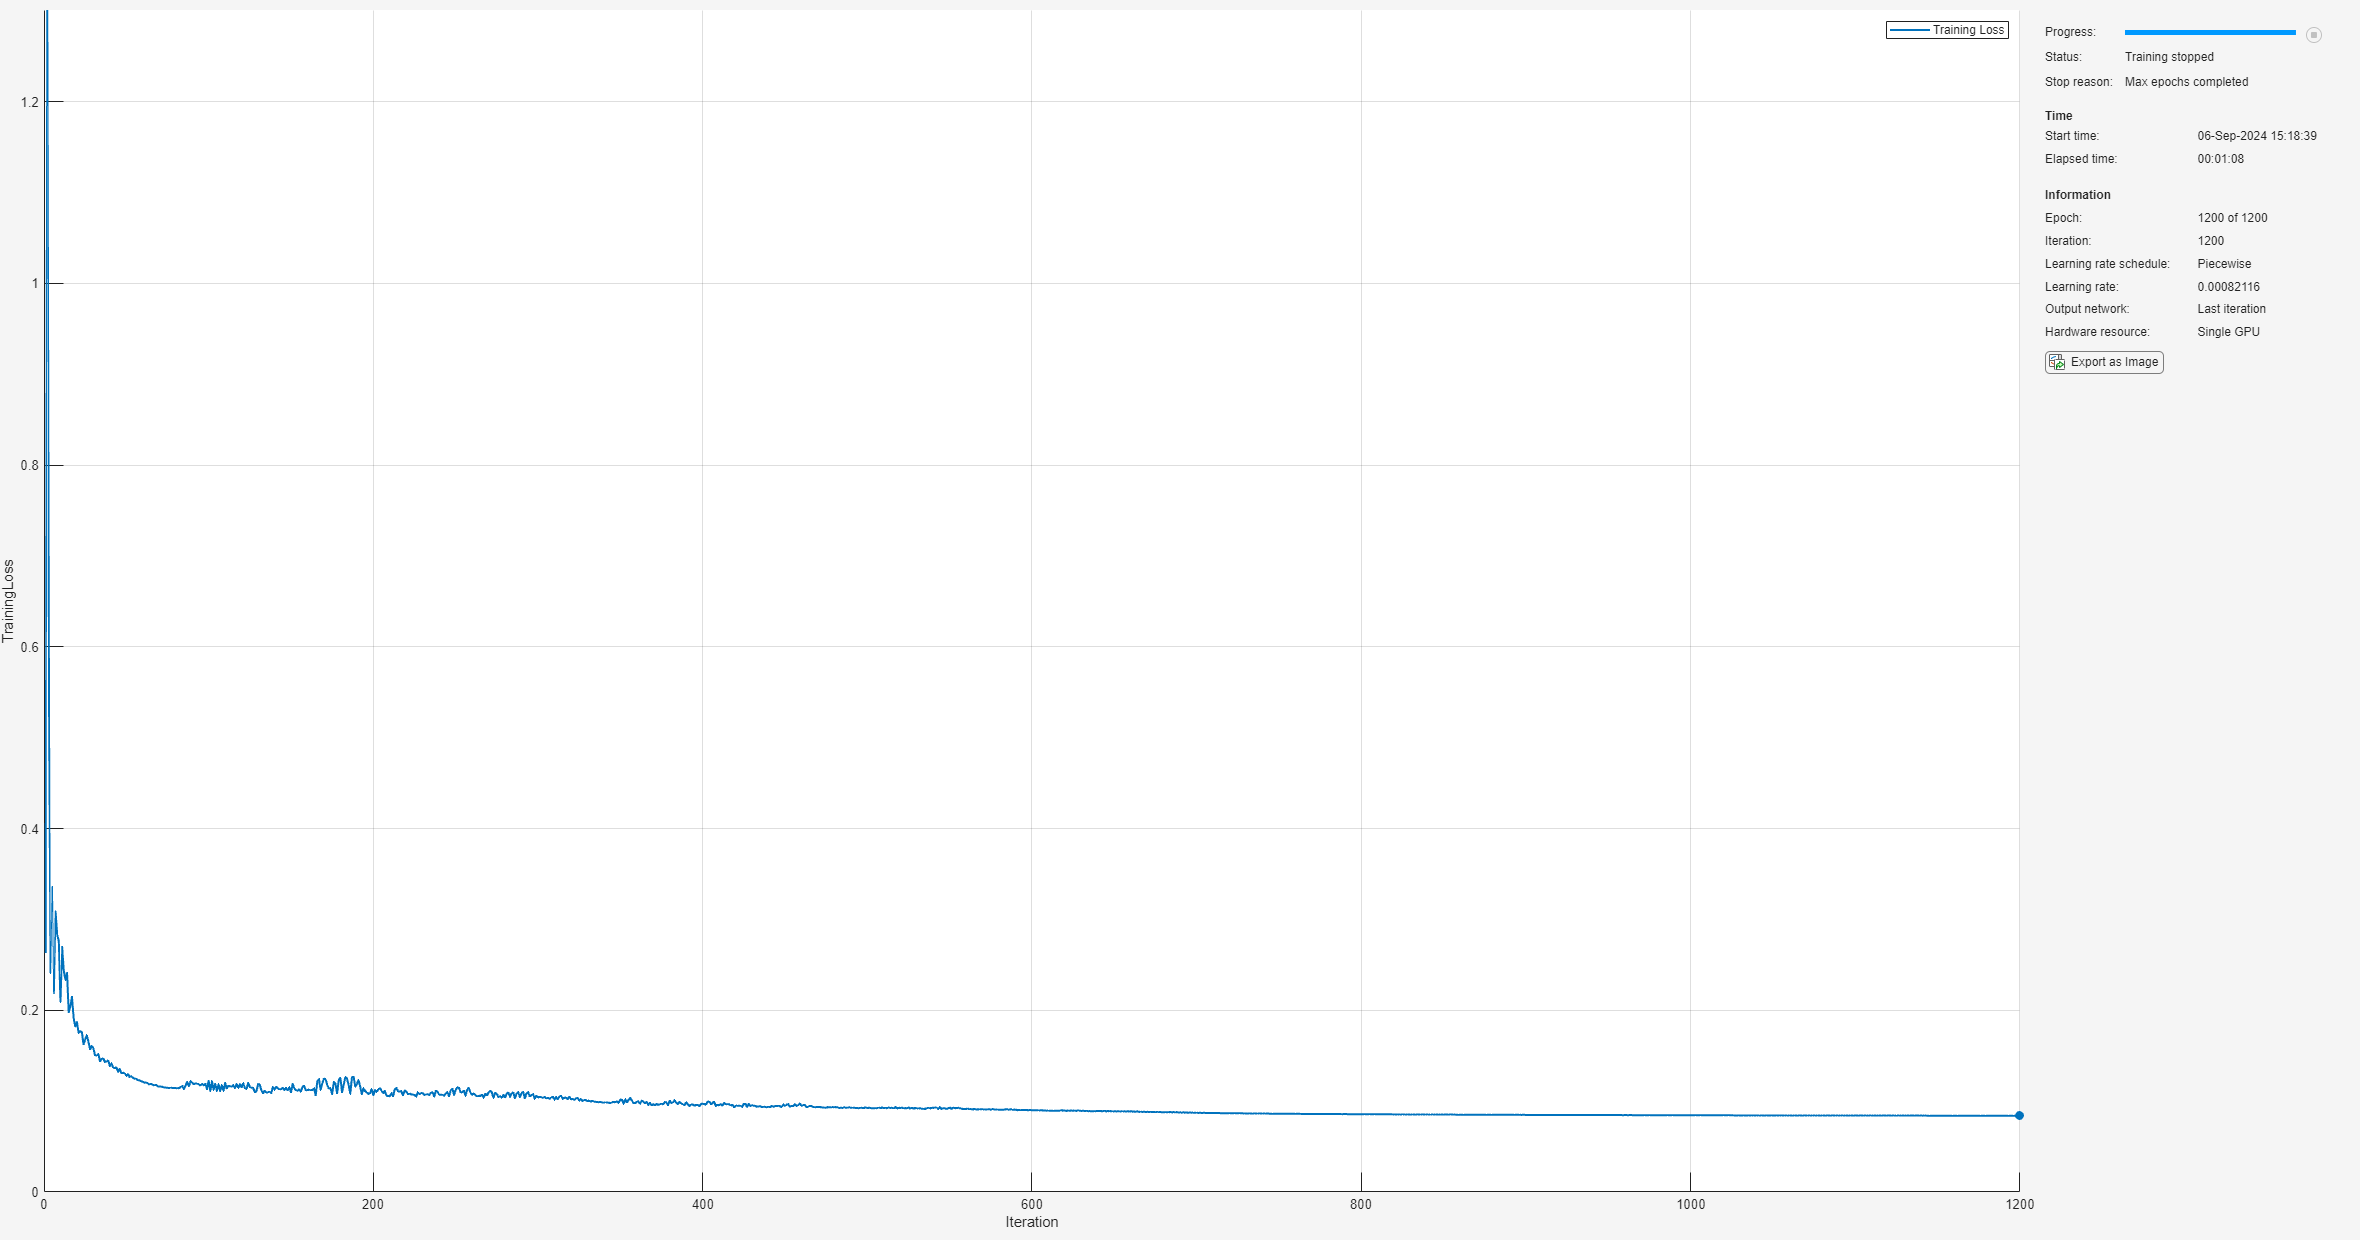

options = trainingOptions("adam", ...
    Plots="training-progress", ...
    MaxEpochs=maxEpochs, ...
    InitialLearnRate=initialLearnRate, ...
    MiniBatchSize=numSamples, ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.9, ...
    LearnRateDropPeriod=30, ...
    Shuffle="never");
trained_mlpnet = trainnet(mbqTrain,mlpnet,lossMetric,options);

Evaluate the accuracy on an independent random sampling from the interval `[-1,1]`. Observe that the loss against the underlying monotonic signal here is higher as the network has fitted to the sinusoidal contamination.

lossAgainstUnderlyingSignal = computeLoss(trained_mlpnet,xTest,tTest,lossMetric)

lossAgainstUnderlyingSignal = single
0.0696

## Network Comparison

Compare the shape of the solution by sampling the training data and plotting this for both networks.

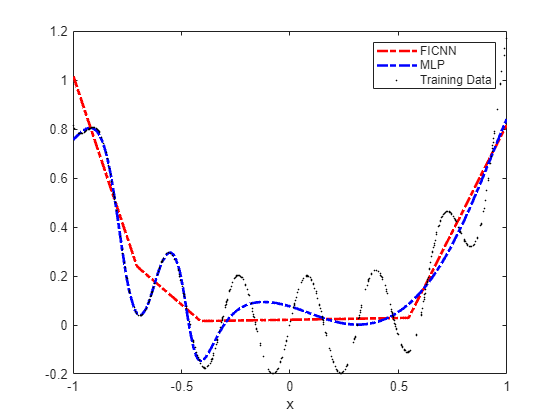

ficnnPred = predict(trained_ficnnet,xTrain);
mlpPred = predict(trained_mlpnet,xTrain);

figure;
plot(xTrain,ficnnPred,"r-.",LineWidth=2)
hold on
plot(xTrain,mlpPred,"b-.",LineWidth=2)
plot(xTrain,tTrain,"k.",MarkerSize=0.1)
xlabel("x")
legend("FICNN","MLP","Training Data")

It is visually evident that the MLP solution is not convex over the interval but the FICNN is convex, owing to its convex construction and constrained learning.

## Guaranteed Bounds for FICNN

As discussed in [AI Verification: Convex](matlab:open('..\..\..\documentation\AI-Verification-Convexity.md')), fully input convex neural networks allows you to efficiently compute bounds over intervals by only evaluating the function, and its derivative, at the boundary. These boundedness guarantees play an important role in guaranteeing behavior on continuous regions of input space. Moreover, you only need to sample a small, finite number of test points. You can use more test points to tighten the bounds in different regions as needed.

numIntervals = 12;
intervalSet = linspace(-1,1,numIntervals+1);

Collect the set of vertices into a cell array for use in the `computeICNNBoundsOverNDGrid` function. As this is 1-D, pass the interval as a cell into the function.

V = {intervalSet};

Compute the network value at the vertices and also guaranteed output bounds over the subintervals specified by the set of vertices.

To refine the lower bound, set the name-value argument `RefineLowerBounds=true`. As described in [AI Verification: Convex](matlab:open('..\..\..\documentation\AI-Verification-Convexity.md')), this performs convex optimization over the intervals for which a minimum cannot be determined using the derivative conditions. If this option is set to false, `NaN` values are returned in the grid locations where the conditions on the derivatives of the network at the grid vertices are not sufficient to determine the minimum, as discussed in [AI Verification: Convex](matlab:open('..\..\..\documentation\AI-Verification-Convexity.md')).

Note that `RefineLowerBounds=true` requires Optimization Toolbox. If you do not have this toolbox, then the `netMin` variable will have `NaN` values in the positions of the intervals the minimum cannot be determined and the plots below will not show a lower bound over this interval.

[netMin,netMax] = convexNetworkOutputBounds(trained_ficnnet,V,RefineLowerBounds=true);

Plot the bounds.

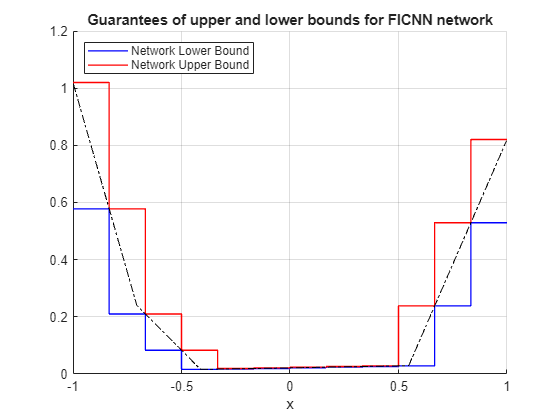

v = reshape([V{1}(1:end-1); V{1}(2:end)], 1, []);
yMax = reshape([netMax{1}'; netMax{1}'], 1, []);
yMin = reshape([netMin{1}'; netMin{1}'], 1, []);

figure
grid on
hold on
plot(v, yMin, "b-", "LineWidth", 1);
plot(v, yMax, "r-", "LineWidth", 1);
plot(xTrain,ficnnPred,"k-.")
hold off
xlabel("x")
legend("Network Lower Bound","Network Upper Bound",Location="northwest")
title("Guarantees of upper and lower bounds for FICNN network");

## Violated Bounds for MLP

Repeat the analysis above for the MLP. Since this has not been trained with enforced convexity, the bounding guarantees do not hold and you observe violations of the bounds over the same interval.

[netMin,netMax,netPred] = convexNetworkOutputBounds(trained_mlpnet,V,RefineLowerBounds=true);

Plot the bounds.

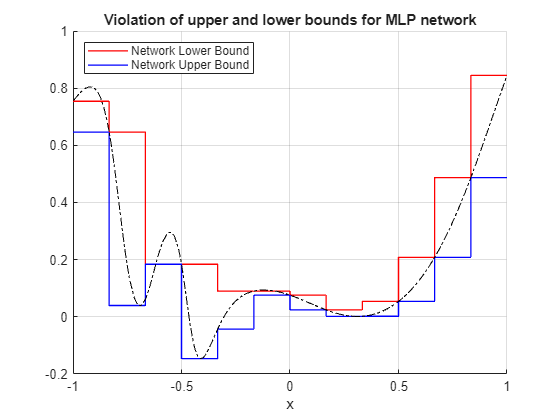

v = reshape([V{1}(1:end-1); V{1}(2:end)], 1, []);
yMax = reshape([netMax{1}'; netMax{1}'], 1, []);
yMin = reshape([netMin{1}'; netMin{1}'], 1, []);

figure; % Create a new figure
hold on;
plot(v, yMax, "r-", "LineWidth", 1);
plot(v, yMin, "b-", "LineWidth", 1);
plot(xTrain,mlpPred,"k-.")
hold off
xlabel("x");
legend("Network Lower Bound","Network Upper Bound",Location="northwest")
title("Violation of upper and lower bounds for MLP network");
grid on;

## Helper Functions

function loss = computeLoss(net,X,T,lossMetric)
Y = predict(net,X);
switch lossMetric
    case "mse"
        loss = mse(Y,T);
    case "mae"
        loss = mean(abs(Y-T));
end
end

*Copyright 2024 The MathWorks, Inc.*